# **DSP Final Exam                                                                             Ebad Syed**

## **Question 1**

**Design an IIR digital filter specified by H(z), that when is used in a prefilter A/𝐷 → 𝐻(𝑧) → 𝐷/𝐴 structure, will satisfy the following equivalent analog specifications:**

**S1-----2dB cutoff at 75𝜋 rad/sec.**

**S2-----40dB attenuation at and pass 500𝜋 rad/sec.**

**S3------Monotonic stopband and passband.**

**S4------Sampling rate of 1500 samples/sec.**

**Find:**

**a. H(z)**

**b. Plot |𝐻(𝑗𝜔)|**

## **Answer 1**

1500 Hz = 9,424.77796 rad/s 

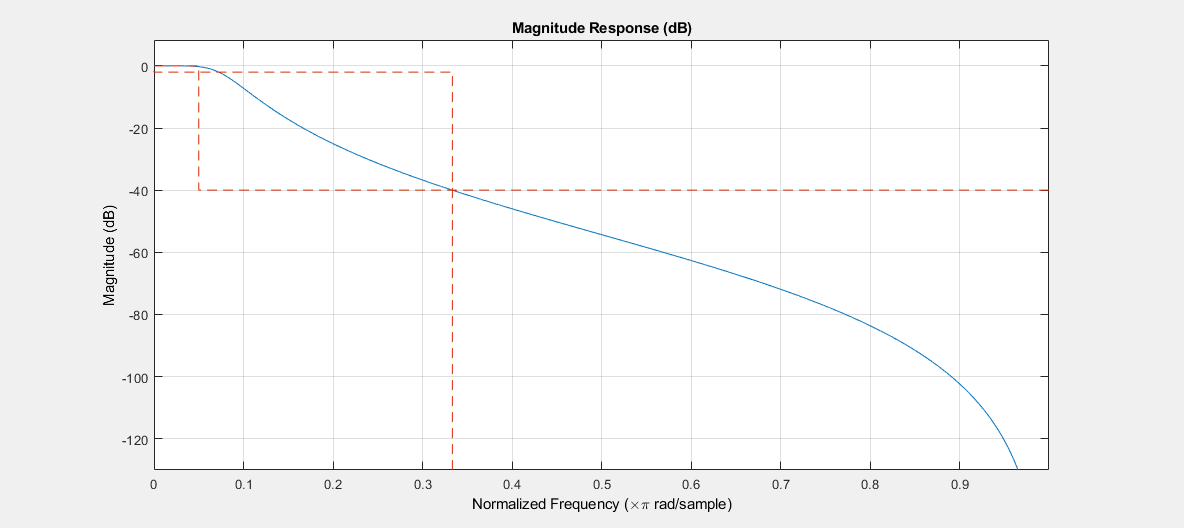

fs = 9424.77796; % Sampling Frequency in Radians per Seconds 

wp = (75*pi)/(fs/2); % digital Passband converted to Normalized freq
ws = (500*pi)/(fs/2); % digital Stopband converted to Normalized freq

Ap = 2; % Passband ripple in dB
As = 40; % Stopband attenuation in dB

% Filter Design
lpFilt = designfilt('lowpassiir','PassbandFrequency',wp, ...
'StopbandFrequency',ws,'PassbandRipple',Ap, ...
'StopbandAttenuation',As);

fvtool(lpFilt)

**Part A Answer**

[b,a] = tf(lpFilt);

**H(z)**

sys = tf(b,a,1/1500)

sys =
 
  0.001502 z^3 + 0.004505 z^2 + 0.004505 z + 0.001502
  ---------------------------------------------------
          z^3 - 2.506 z^2 + 2.127 z - 0.6088
 
Sample time: 0.00066667 seconds
Discrete-time transfer function.



**Part B Answer**

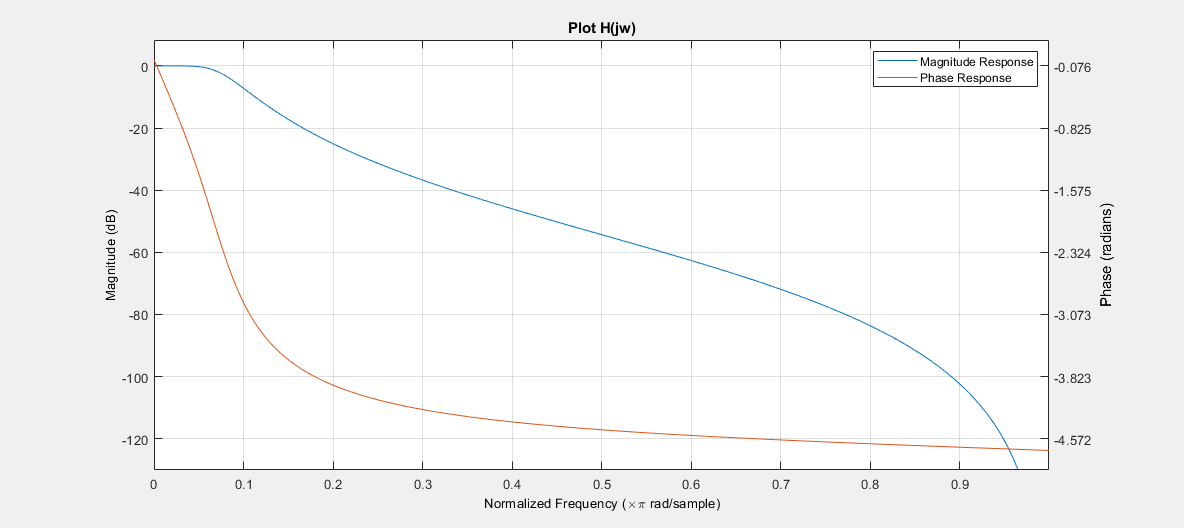

freqz(lpFilt)
legend("Magnitude Response", "Phase Response")
title("Plot H(jw)")

## Question 2

**A filter is specified by its unit sample response h(n), given by ℎ(𝑛) = − 1 /3 𝛿(𝑛 + 1) + 1 /2 𝛿(𝑛) − 1/ 3 𝛿(𝑛 − 1)**

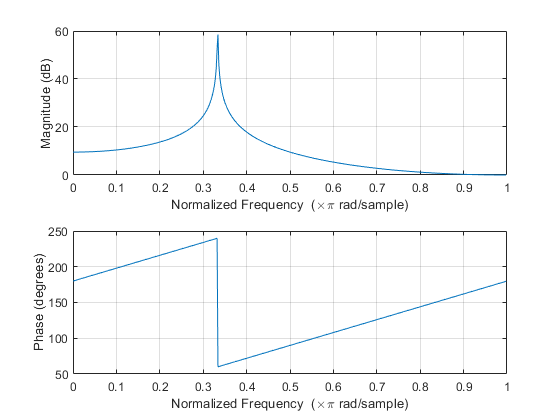

a = [-1/3 1/3 -1/3];
b = [1];
freqz(b,a);

**a. Is it a linear phase filter? Why? **

No because phase response is not linear

**b. Is it a low-pass or high-pass filter? Why?**

Low Pass because passes lower frequency comparatively better

**c. Is it a causal filter? Why?**

It is causal because output only depends on past input and not future

## **Question 3**

**Using the Hann window, design a bandpass filter that will satisfy the following specifications: **

**ωp1 = 0.2π, δp = 0.056, ωs1 = 0.3π, ωs2 = 0.5π, δs = 0.01, ωp2 = 0.65π, δp = 0.056**

## **Answer 3**

Ap = 20 * log10((1 + 0.056)/(1-0.056)) % Passband Ripple in DB

Ap = 0.9738

As = 20 * log10((1 + 0.056)/0.01) % Stopband Ripple in DB

As = 40.4733

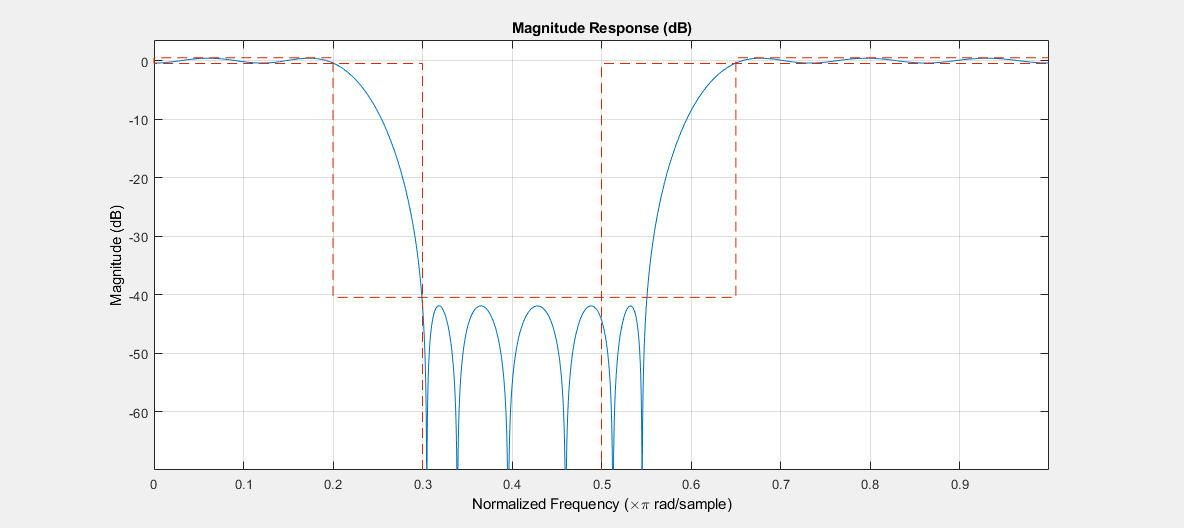

wp1 = 0.2; % digital Passband 1 converted to Normalized freq

ws1 = 0.3; % digital Stopband 1 converted to Normalized freq
ws2 = 0.5; % digital Stopband 2 converted to Normalized freq

wp2 = 0.65; % digital Passband 2 converted to Normalized freq

fir = designfilt('bandstopfir',...
                 'StopbandFrequency1',ws1,'StopbandFrequency2',ws2, ...
                 'StopbandAttenuation',As,'PassbandRipple1',Ap,'PassbandRipple2',Ap,'PassbandFrequency1',wp1,'PassbandFrequency2',wp2);


fvtool(fir)

## **Question 4**

**A lowpass digital filter’s specifications are given by:**

**wp = 0.2pi   Ap = 1dB   ws=0.3pi  As=60dB**

**a) Using bilinear transformation and the Chebyshev type II approximation approach, obtain a system function H(z) in the cascade form that satisfies the above specifications.**

**b) Provide design plots in the form of log-magnitude, phase, group-delay, and impulse responses.**

**c) (c) Determine the exact band-edge frequencies for the given attenuation**

## **Answer 4**

wp = 0.2; % digital Passband Normalized freq 
ws = 0.3; % digital Stopband Normalized freq 
Ap = 1; % Passband ripple in dB
As = 60; % Stopband attenuation in dB

[N,omegac] = cheb2ord(wp,ws,Ap,As)

N = 9

omegac = 0.3000

[C,D] = cheby2(N,Ap,omegac)

C =     0.7095   -0.5859    1.6394   -0.1899    1.0505    1.0505   -0.1899    1.6394   -0.5859    0.7095


D =     1.0000   -1.0783    2.4138   -0.8143    1.5523    0.6268    0.1978    1.1331   -0.2872    0.5033


[B,A] = bilinear(C,D,1)

B =     0.8343   -5.7699   20.7860  -47.0989   73.5864  -80.4917   61.7613  -31.4888    9.8604   -1.3287


A =     1.0000   -7.2972   27.1899  -63.6002  102.0073 -114.5112   89.7929  -46.9087   14.9098   -2.1212


**Answer a)**

sys = tf(B,A,1)

sys =
 
  0.8343 z^9 - 5.77 z^8 + 20.79 z^7 - 47.1 z^6 + 73.59 z^5 - 80.49 z^4 + 61.76 z^3 - 31.49 z^2 + 9.86 z - 1.329
  -------------------------------------------------------------------------------------------------------------
     z^9 - 7.297 z^8 + 27.19 z^7 - 63.6 z^6 + 102 z^5 - 114.5 z^4 + 89.79 z^3 - 46.91 z^2 + 14.91 z - 2.121
 
Sample time: 1 seconds
Discrete-time transfer function.



**Answer b)**

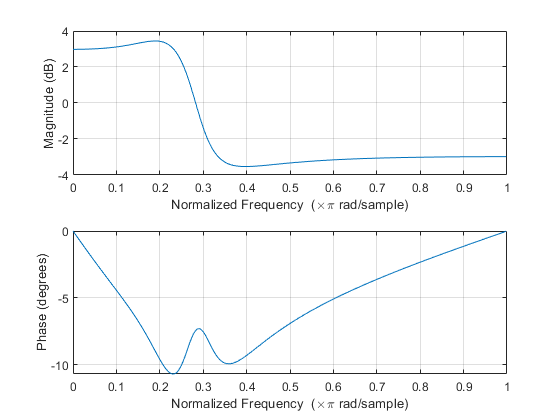

freqz(B,A)

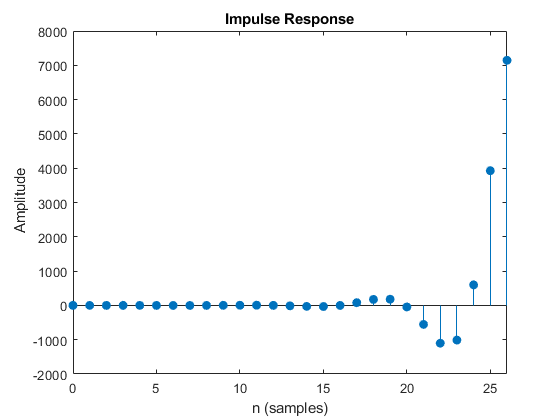

impz(B,A)

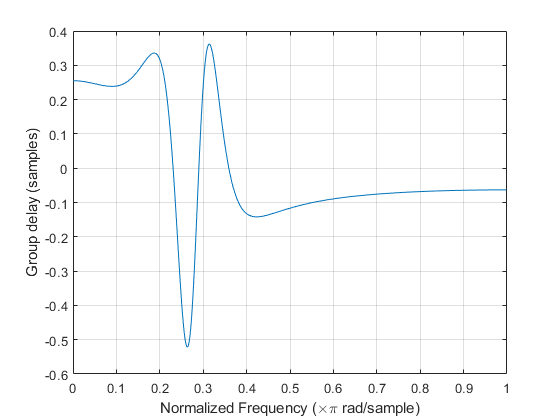

grpdelay(B,A)

**Answer C**

**Exact band Edge Frequency**

cursor_info1

cursor_info1 = 1×2 struct array with fields:
    Target
    Position
    DataIndex


Actual Attenuation is -3dB at ws and 1.3dB at wp

## Question 5

Sampling Frequency = 100;

ℎ(𝑛) = 0.5 𝑛𝑢(𝑛)

a**. What is the digital frequency of 𝑥(𝑡) 𝑖𝑓 𝑥(𝑡) = 5 cos(20𝜋𝑡) ? **

Fs = 100; % Sampling frequency

t = 0:1/Fs:1-1/Fs; % Time

xt = 5* cos(2*10*pi*t) ; %Input Signal

xt = 5* cos(2*10*pi*t) ;

Frequency is 10Hz or 20pi rad/s

Normalized Frequency is 0.1

**b. Find the steady state output, 𝑦𝑠𝑠(𝑡), if 𝑥(𝑡) is the same as in (a).**

**Given  **ℎ(𝑛) = 0.5 𝑛𝑢(𝑛)

H(z) = z/z - 0.5

b = [1 0];
a = [1 -0.5];
sys = tf(b,a,100)

sys =
 
     z
  -------
  z - 0.5
 
Sample time: 100 seconds
Discrete-time transfer function.



yss = filter(b,a,xt)

yss =     5.0000    6.5451    4.8176    0.8637   -3.6132   -6.8066   -7.4484   -5.2693   -1.0896    3.5003    6.7502    7.4202    5.2552    1.0825   -3.5038   -6.7519   -7.4210   -5.2556   -1.0827    3.5037    6.7519    7.4210    5.2556    1.0827   -3.5037   -6.7519   -7.4210   -5.2556   -1.0827    3.5037    6.7519    7.4210    5.2556    1.0827   -3.5037   -6.7519   -7.4210   -5.2556   -1.0827    3.5037    6.7519    7.4210    5.2556    1.0827   -3.5037   -6.7519   -7.4210   -5.2556   -1.0827    3.5037


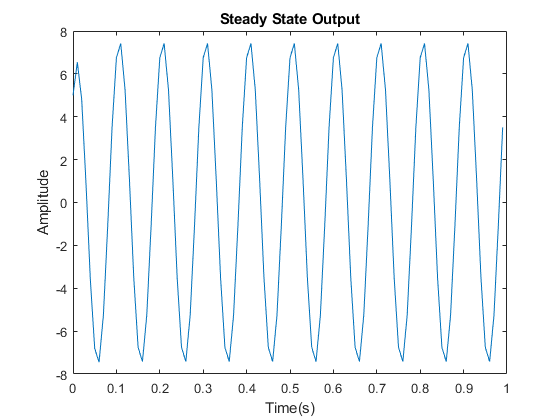

plot(t,yss)
title("Steady State Output")
ylabel("Amplitude")
xlabel("Time(s)")

**c. Find the steady state output, 𝑦𝑠𝑠(𝑡), if 𝑥(𝑛) = 5𝑢(𝑡).**

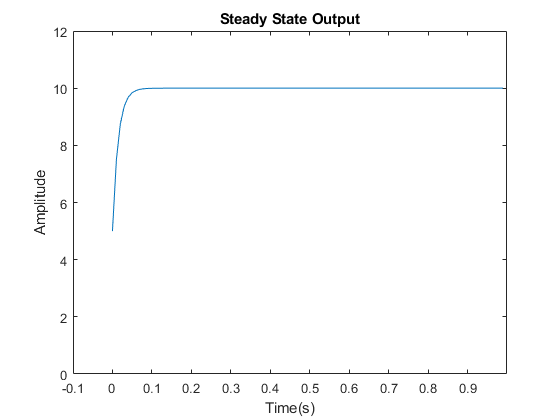

n = ones(1,100);
xn = 5 * n;

yss2 = filter(b,a,xn);

plot(t,yss2)
title("Steady State Output")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([0 12])
xlim([-0.1 1])

** d. Find two other 𝑥(𝑡)’s, different analog frequency, that will give the same steady state output as 𝑥(𝑡) = 5 cos(20𝜋𝑡).**